% Wing Parameters Inputs:
% Program: Inputs are assigned manually from user input
% Import: Inputs are assigned from a xlsx file in the format of the optimization export
% Optimization: Inputs are assigned from the Optimization Algorithm, only
% works if the optimzation is actually run

wing_parameter_input = WingParameterInput.Import;
parameters_path = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Output\NASA_Model_8.xlsx"; % Path for Import

if wing_parameter_input == WingParameterInput.Import
    
    parameters = readtable(parameters_path); % Read Parameters from xlsx file

    % Extract Input Parameters
    aspect_ratio = parameters.Var2(1);
    taper_ratio =  parameters.Var2(2);
    geo_twist_angle = parameters.Var2(3);
    sweep_angle = parameters.Var2(4);
    dihedral_angle = parameters.Var2(5);
    flap_percent = parameters.Var2(6);
    flap_angle = parameters.Var2(7);
    aoa_tip_0 = parameters.Var2(8);
    aoa_root_0 = parameters.Var2(9);
    root_chord = parameters.Var2(10);
    
    [~, file_name, ~]  = fileparts(parameters_path);
    wing_name = char(file_name);

else

    % Enter inputs manually here if selecting Program Input

    aspect_ratio = 10;  % Ratio of Wing Span to Width   
    taper_ratio = 1; % Ratio of Tip to Root Chord 

    % Enter Following in Degrees
    geo_twist_angle = 0; % Angle to which wing is twisted via washout
    sweep_angle = 0; % Angle to which the wing is sweeped from the quarter chord
    dihedral_angle = 0; % Angle of Wing Dihedral                                
    flap_angle = 0; % Angle of Flaps

    % Enter a number from 1 to 100
    flap_percent = 0; % Percentage of wing which is flapped

    wing_name = 'TestWing';  
    
end


% Optimizations: Usually run indepedent of rest of program
% Can be used to generate wing parameter inputs used by the rest of the program

drag_optimization = false; % Run Drag Optimization
CL_optimization = false; % Run Lift Optimization

% Instantiate variables for optimization
aoa_tip_0 = 0;
aoa_root_0 = 0;
root_chord = 1; % Root Chord length in meters, Not key wing parameter as aspect ratio is used to determine relative length and width   

global panel_number aoa_vector elliptical_planform wake_alignment dihedral_twist_correction non_linear_correction compressibility_correction freestream_velocity airfoil_name mean_chord_reynolds airfoil_database_path decambering_threshold max_decambering_iterations

% Intervals of wing parameters for the optimization
aspect_ratio_interval = [5 12];
taper_ratio_interval = [0.1 1];
geo_twist_angle_interval = [0 0];
sweep_angle_interval = [-15 15];
dihedral_angle_interval = [0 0];
flap_percent_interval = [0 0];
flap_angle_interval = [0 0];
aoa_tip_0_interval = [0 0];
aoa_root_0_interval = [0 0];
root_chord_interval = [1 1];

max_iterations = 500; % Maximum iterations the optimizer will run before quiting. Increasing this value will increase computation time

export_optimization = false; % Export Optimized Parameters to an xlsx file

if drag_optimization

   wing_parameters = optimize_CD(aspect_ratio_interval, taper_ratio_interval, geo_twist_angle_interval, sweep_angle_interval, dihedral_angle_interval, flap_percent_interval, flap_angle_interval, aoa_tip_0_interval, aoa_root_0_interval, root_chord_interval, max_iterations, aspect_ratio, taper_ratio, geo_twist_angle, sweep_angle, dihedral_angle, flap_percent, flap_angle, aoa_tip_0, aoa_root_0, root_chord, export_optimization);
    
end

if CL_optimization

   wing_parameters = optimize_CL(aspect_ratio_interval, taper_ratio_interval, geo_twist_angle_interval, sweep_angle_interval, dihedral_angle_interval, flap_percent_interval, flap_angle_interval, aoa_tip_0_interval, aoa_root_0_interval, root_chord_interval, max_iterations, aspect_ratio, taper_ratio, geo_twist_angle, sweep_angle, dihedral_angle, flap_percent, flap_angle, aoa_tip_0, aoa_root_0, root_chord, export_optimization);

end

if (drag_optimization || CL_optimization) && wing_parameter_input == WingParameterInput.Optimization

     % Assign Optimzation Wing Parameters to Program Wing Parameters
     aspect_ratio = wing_parameters(1);
     taper_ratio =  wing_parameters(2);
     geo_twist_angle = wing_parameters(3);
     sweep_angle = wing_parameters(4);
     dihedral_angle = wing_parameters(5);
     flap_percent = wing_parameters(6);
     flap_angle = wing_parameters(7);
     aoa_tip_0 = wing_parameters(8);
     aoa_root_0 = wing_parameters(9);
     root_chord = wing_parameters(10);

end

% Program Parameters

panel_number = 20; % # of Panels in Simulation. Determines Quality of Results and Program Resource Usage. Must be Even 
elliptical_planform = false; % Models Wing to be elliptical
              
dihedral_twist_correction = false;   % Corrects Vortex Coefficients to account for Dihedral and Twist
wake_alignment = WakeAlignment.Freestream; % Determines the alignment of wakes. Freestream aligns wake with airflow with respect to angle of attack. Wing aligns to airflow with respect to the wing.
compressibility_correction = false; % Corrects for compressibility using Prandtl-Glauert Transformation
non_linear_correction = false; % Uses Decambering Algorithm to approximate non-linear flow, can be computationally expensive if running with large angle of attack vectors and/or high panel numbers
do_non_linear_correction_for_all_aoa = false; % Run Non-Linear Correction for all angles of attack, if false will run only at the specified angle of attack index

decambering_threshold = 0.001; % Threshold for difference between program and experimental C_L in decambering algorithm
max_decambering_iterations = 500; % Maximum iterations before decambering algorithm finishes

freestream_velocity = 1; % Freestream Velocity in Meters/Second 
mach = 0.9; % Mach Number for Compressibility Correction, must be below 1

grid_number = 70; % Number of Grids in each dimension for Wake Plot. Increasing this improves Quality of Wake Plot but increases computation time

if ~compressibility_correction  % Set Mach number to zero if Compressibility Correction is not used
    mach = 0.0;
end

aoa_init = 15; % Initial Angle of Attack 
aoa_final = 20; % Final Angle of Attack 
aoa_step = 1; % Step Size for Vector

% Slider Mins and Maxes to conform with MATLAB Slider Behavior when changing boundaries
aoa_slider_min = aoa_init - 1; 
aoa_slider_max = aoa_final + 1;

selected_aoa = 15; % Selected Angle of Attack for Plots 
array_index = (selected_aoa - aoa_init) / aoa_step + 1; % Array Index of Selected Angle of Attack

aoa_vector = aoa_init:aoa_step:aoa_final; % Angle of Attack Vector

mean_chord_reynolds = 9e6; % Reynolds Number at Mean Chord, used for non-linear calculation

plot_geometry = true; % Plots 3D Graph of Wing Geometry 
plot_lift = true; % Plots Lift, C_L Distrbution and C_L over Angle of Attack. If non-linear correction is used, also plots non-linear lift, sectional aoa, and decambering angle distributions                         
plot_drag = true; % Plots Induced Angle of Attack, C_D Distributions and Drag Polar
plot_wake = false; % Plots a 3D Wake

export_geometry = true; % Exports Geometry Plots
export_lift = true; % Exports Lift Plots
export_drag = true; % Exports Drag Plots
export_wake = false; % Exports Wake Plot
export_wing_input_parameters = false; % Exports Wing Input Parameters, Can be imported to run program again

plot_aoa_all =  true; % Plots Data for All Angles of Attack 
do_aoa_labels = true; % If Plot all Angles of Attack, labels each curve with its Angle of Attack

% Export Name Configuration
include_panel_number_in_run_name = false; 
include_aoa_in_run_name = false;

export_name = wing_name;

if include_panel_number_in_run_name

    export_name = append([export_name, '_1000_Panel']);
 
end

if include_aoa_in_run_name

    export_name = append([export_name, '_', num2str(aoa_vector(1)), '°_to_', num2str(aoa_vector(end)),'°']);

end

% Airfoil Selection

% Determines if Airfoil Database is used to determine angle of attack with 0 CL
use_af_data_root = true;                      
use_af_data_tip = true;

% Airfoil Database Path. Feel free to add additional data for other airfoils if needed. 
% VPM-Data-Analysis can be used to approximate angle of attack with 0 CL assuming potential flow
airfoil_database_path = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\Airfoil Data.xlsx";  

% Names of Airfoils Selected from Database
root_airfoil = 'NACA_23012';                           
tip_airfoil = 'NACA_23012';

root_airfoil_path = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\NACA_4418_Kutta_Lift_Model.xlsx"; % Use if getting value from Regression Model
tip_airfoil_path = "C:\Users\asing\OneDrive\Documents\GitHub\Weissinger-Data-Analysis\Airfoil_Data\NACA_23012_Kutta_Lift_Model.xlsx";  % Keep same as first path for no airfoil twist

if use_af_data_root && wing_parameter_input == WingParameterInput.Program

   [aoa_root_0, root_airfoil] = aoa_zero_database(root_airfoil, airfoil_database_path);

else

   [aoa_root_0, root_airfoil] = aoa_zero_regression(root_airfoil_path);

end


if use_af_data_tip && wing_parameter_input == WingParameterInput.Program

    [aoa_tip_0, tip_airfoil] = aoa_zero_database(tip_airfoil, airfoil_database_path);
   

else

    [aoa_tip_0, tip_airfoil] = aoa_zero_regression(tip_airfoil_path);

end

airfoil_name = root_airfoil; % Used for Decmbering Calculation

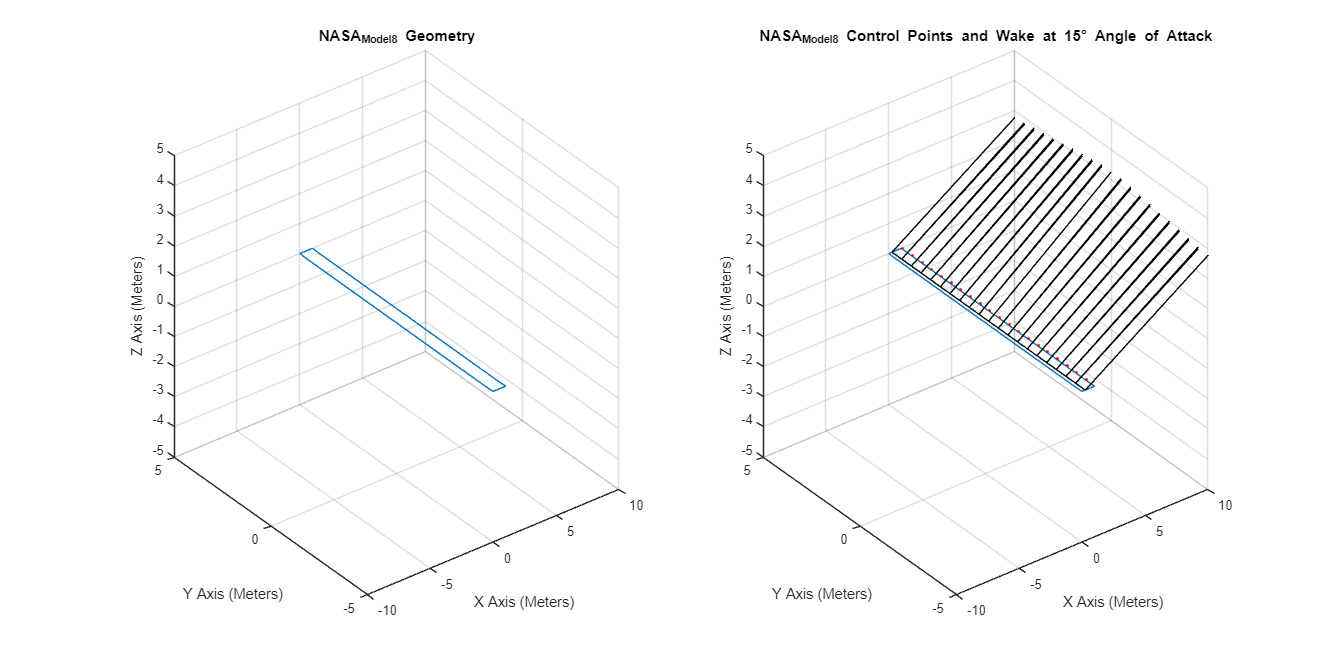

% Wing Geometry Extrapolation

% Tip Chord is zero if wing is elliptical
if elliptical_planform                              

    tip_chord = 0;

else

    tip_chord = taper_ratio * root_chord;

end

% Wing Span and Wing Reference Area Calculation
wing_span = cosd(dihedral_angle) * aspect_ratio * root_chord * (1 + taper_ratio)/2;
wing_reference_area = (1+taper_ratio) * root_chord * wing_span/2;

% Instantiate Control Point Cells
x_control = cell(1, size(aoa_vector, 2));
y_control = cell(1, size(aoa_vector, 2));
z_control = cell(1, size(aoa_vector, 2));

% Generate Wing Geometry
for i = 1:size(aoa_vector, 2)

    [x_vortex_1, y_vortex_1, z_vortex_1,x_vortex_2, y_vortex_2, z_vortex_2, x_control{i}, y_control{i}, z_control{i}, chord, twist, aoa_0_dist] = generate_wing_geometry(panel_number, wing_span, root_chord, tip_chord, sweep_angle, geo_twist_angle, dihedral_angle, elliptical_planform, aoa_tip_0, aoa_root_0, aoa_vector(i), flap_percent, flap_angle, wake_alignment);

end


wake_length = 10; % Wake Length for Geometry Plot

% Geometry Plot
if plot_geometry
   
      plot_wing_geometry(panel_number, wing_span, root_chord, tip_chord, geo_twist_angle, twist, chord, x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, x_control{array_index}, y_control{array_index}, z_control{array_index}, selected_aoa, aoa_0_dist, wake_alignment, wake_length, wing_name, export_geometry, export_name);
    
end

% LHS Lift Matrix

LHS_lift_matrix = cell(1, size(aoa_vector,2));

for i = 1:size(aoa_vector, 2)

    LHS_lift_matrix{i}  = calc_LHS_lift_matrix(x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, x_control{i}, y_control{i}, z_control{i}, panel_number, aoa_vector(i), aoa_0_dist, twist, dihedral_angle, dihedral_twist_correction, wake_alignment);

end

% RHS Lift Matrix

RHS_lift_matrix = cell(1, size(aoa_vector,2));

for i = 1:size(aoa_vector, 2)

    RHS_lift_matrix{i} = calc_RHS_lift_matrix(aoa_vector(i), aoa_0_dist, twist, dihedral_angle, freestream_velocity, panel_number);

end

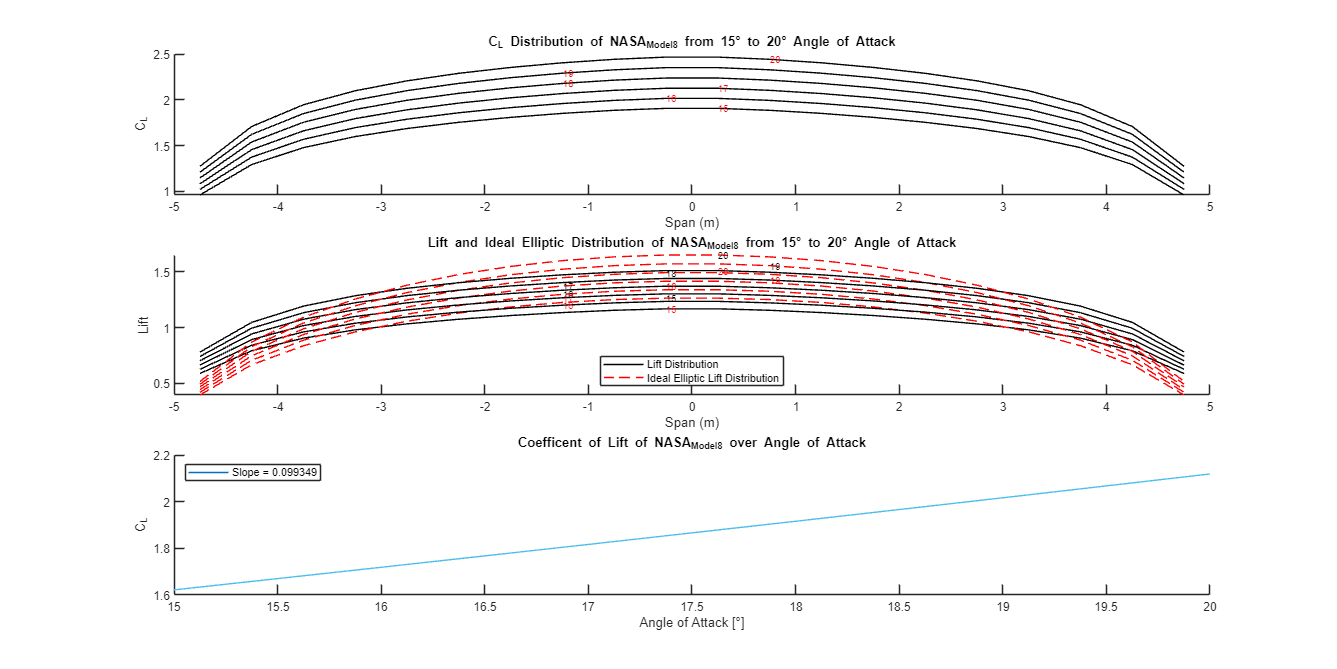

% Coefficent of Lift Calculation Theorem, Plot, and Export

% Calculate Lift via Kutta Joukowski
[circulation, lift, CL, total_CL] = calc_CL(aoa_vector, LHS_lift_matrix, RHS_lift_matrix, freestream_velocity, panel_number, mach, chord, wing_reference_area, wing_span);


% Plot Lift
if plot_lift

     [CL_aoa] = plot_CL_master(y_control{1}, lift, CL, total_CL, aoa_vector, freestream_velocity, wing_reference_area, wing_span, panel_number, array_index, wing_name, export_lift, plot_aoa_all, do_aoa_labels, export_name);

end

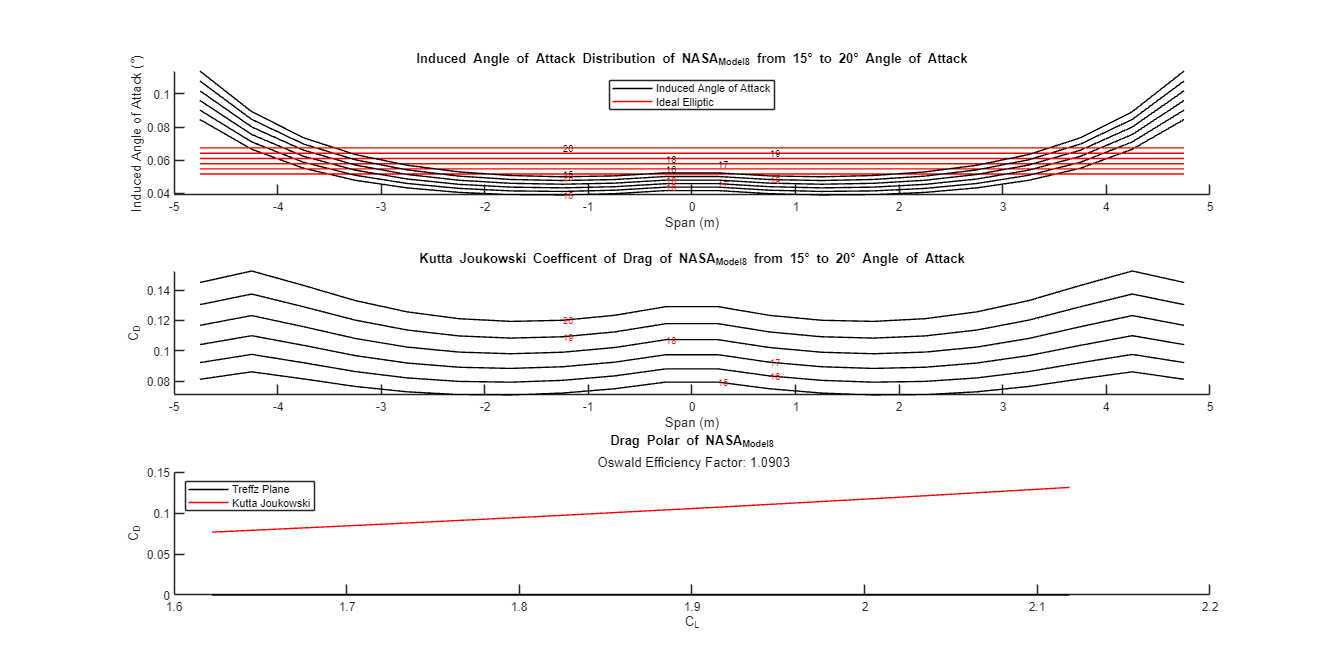

% Induced Drag Calculation, Plot, and Export

LHS_kutta_drag_matrix_z = cell(1, size(aoa_vector,2));

% Calculate Drag using Kutta Joukowski Theorem
for i = 1:size(aoa_vector, 2)  

    [~, ~, LHS_kutta_drag_matrix_z{i}] = calc_induced_kutta_drag_matrix(x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, sweep_angle, dihedral_angle, panel_number, aoa_vector(1), aoa_0_dist, wake_alignment);

end

[induced_aoa, induced_kutta_drag, induced_kutta_CD, total_induced_kutta_drag, total_induced_kutta_CD] = calc_induced_kutta_drag(aoa_vector, chord, LHS_kutta_drag_matrix_z, circulation, mach, freestream_velocity, wing_span, wing_reference_area, panel_number);

% Calculate Drag using Treffz Plane Method
treffz_plane_x_wake = cell(1, size(aoa_vector,2));
z_velocity = cell(1, size(aoa_vector,2));

total_induced_treffz_plane_drag = zeros(1,size(aoa_vector, 2));
total_induced_treffz_plane_CD = zeros(1,size(aoa_vector, 2));

for i = 1:size(aoa_vector,2)

    treffz_plane_x_wake{i} = 0 * x_control{i} + 100 * wing_span;

    for j = 1:panel_number

        [~, ~, z_velocity{i}(j)] = calc_induced_treffz_drag_velocity(x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, treffz_plane_x_wake{i}(j), y_control{i}(j), z_control{i}(j), panel_number, aoa_vector(i), aoa_0_dist, wake_alignment, circulation{i});

    end

    [total_induced_treffz_plane_drag(i), total_induced_treffz_plane_CD(i)] = calc_induced_treffz_drag(circulation{i}, z_velocity{i}, wing_span, panel_number, mach, wing_reference_area, freestream_velocity);

end

% Plot Drag
if plot_drag

    [oswald_efficiency_factor] = plot_CD_master(y_control{1}, induced_aoa, aoa_vector, induced_kutta_CD, total_induced_kutta_CD, total_induced_treffz_plane_CD, total_CL, freestream_velocity, aspect_ratio, wing_span, wing_reference_area, panel_number, array_index, plot_aoa_all, wing_name, export_drag, do_aoa_labels, export_name);

end

% Non-Linear Lift Calculation, Plot, and Export
if non_linear_correction && ~compressibility_correction

    % Calculate Max C_L at Given Reynolds Number
    [reynolds_CL_max] = calc_reynolds_max_CL(taper_ratio, root_chord, mean_chord_reynolds, chord, panel_number, airfoil_database_path, airfoil_name);

    non_linear_circulation = cell(1, size(aoa_vector, 2));
    CL_non_linear = cell(1, size(aoa_vector, 2));
    aoa_sectional = cell(1, size(aoa_vector, 2));
    decambering_angle = cell(1, size(aoa_vector, 2));
    total_CL_non_linear = zeros(1, size(aoa_vector, 2));
    iteration = zeros(1, size(aoa_vector, 2));

    % Calculate Non-Linear Lift via Decambering Method
    if do_non_linear_correction_for_all_aoa

        for i = 1:size(aoa_vector,2)
    
            [CL_non_linear{i}, total_CL_non_linear(i), aoa_sectional{i}, iteration(i), non_linear_circulation{i}] = calc_non_linear_CL(CL{i}, LHS_lift_matrix{i}, chord, aoa_0_dist, twist, aoa_vector(i), wing_span, wing_reference_area, freestream_velocity, panel_number, airfoil_name, dihedral_angle, reynolds_CL_max, airfoil_database_path, decambering_threshold, max_decambering_iterations);
    
            decambering_angle{i} = -(CL_non_linear{i} - CL{i}) / (2 * pi);
    
        end
       
    else

         [CL_non_linear{array_index}, total_CL_non_linear(array_index), aoa_sectional{array_index}, iteration(array_index), non_linear_circulation{array_index}] = calc_non_linear_CL(CL{array_index}, LHS_lift_matrix{array_index}, chord, aoa_0_dist, twist, selected_aoa, wing_span, wing_reference_area, freestream_velocity, panel_number, airfoil_name, dihedral_angle, reynolds_CL_max, airfoil_database_path, decambering_threshold, max_decambering_iterations);
    
         decambering_angle{array_index} = -(CL_non_linear{array_index} - CL{array_index}) / (2 * pi);

    end
   
    % Plot Non-Linear Lift
    if plot_lift

        plot_CL_non_linear_master(y_control{1}, CL, CL_non_linear, total_CL, total_CL_non_linear, aoa_vector, aoa_sectional, decambering_angle, array_index, wing_name, export_lift, plot_aoa_all, do_aoa_labels, export_name, do_non_linear_correction_for_all_aoa);

    end

end

% Wake Plot and Export

if plot_wake

    if non_linear_correction

        [x_mesh, y_mesh, z_mesh]  = plot_wake_master(grid_number, wing_span, wake_alignment, aoa_vector, x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, panel_number, aoa_0_dist, non_linear_circulation, freestream_velocity, array_index, wing_name, export_name, export_wake);

    else

        [x_mesh, y_mesh, z_mesh]  = plot_wake_master(grid_number, wing_span, wake_alignment, aoa_vector, x_vortex_1, x_vortex_2, y_vortex_1, y_vortex_2, z_vortex_1, z_vortex_2, panel_number, aoa_0_dist, circulation, freestream_velocity, array_index, wing_name, export_name, export_wake);

    end
   
end

% Export Wing Parameters

if export_wing_input_parameters

    wing_parameters = transpose([aspect_ratio taper_ratio geo_twist_angle sweep_angle dihedral_angle flap_percent flap_angle aoa_tip_0 aoa_root_0 root_chord]);

    export_wing_parameters(wing_parameters, wing_name);

end